## 问题4

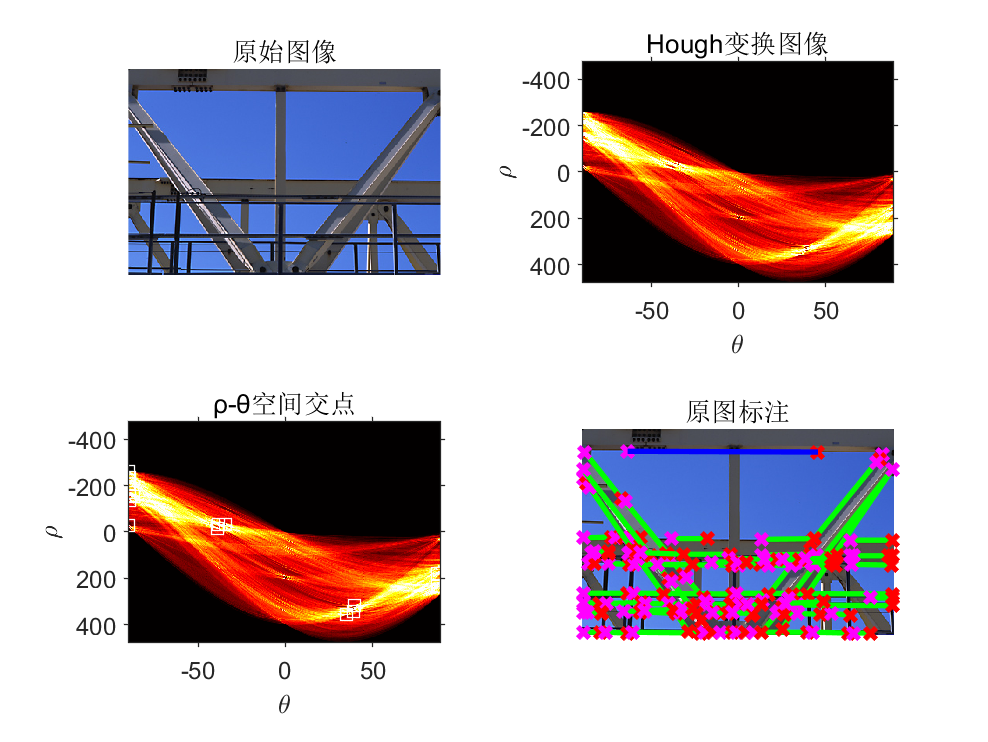

clf;
tiledlayout(2,2)
RGB = imread('gantrycrane.png');
I = im2gray(RGB);
BW = edge(I,'canny');
[H,T,R] = hough(BW,'RhoResolution',2,'Theta',-90:0.5:89);

nexttile
imshow(RGB);
title('原始图像');

nexttile
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough变换图像');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
colormap(gca,hot);

nexttile
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('ρ-θ空间交点');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
colormap(gca,hot);
hold on
P  = houghpeaks(H,20,'threshold',ceil(.5*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');
hold off

nexttile
lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',7);
imshow(RGB), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','magenta');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   len = norm(lines(k).point1 - lines(k).point2);
   if (len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','blue');
title('原图标注')


sprintf(['线条数为' num2str(length(lines))])

ans = '线条数为88'

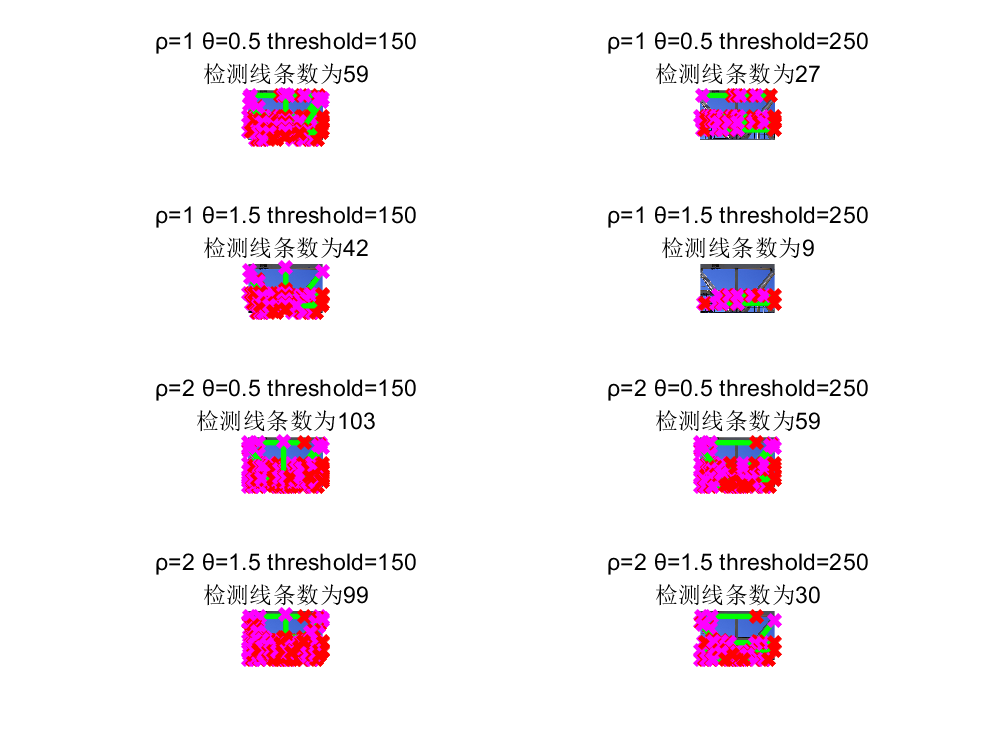

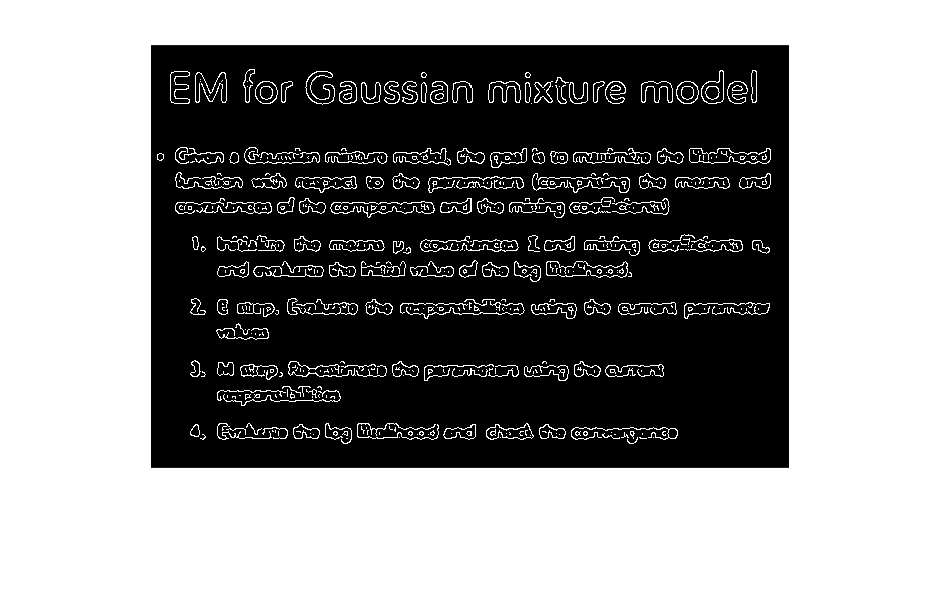

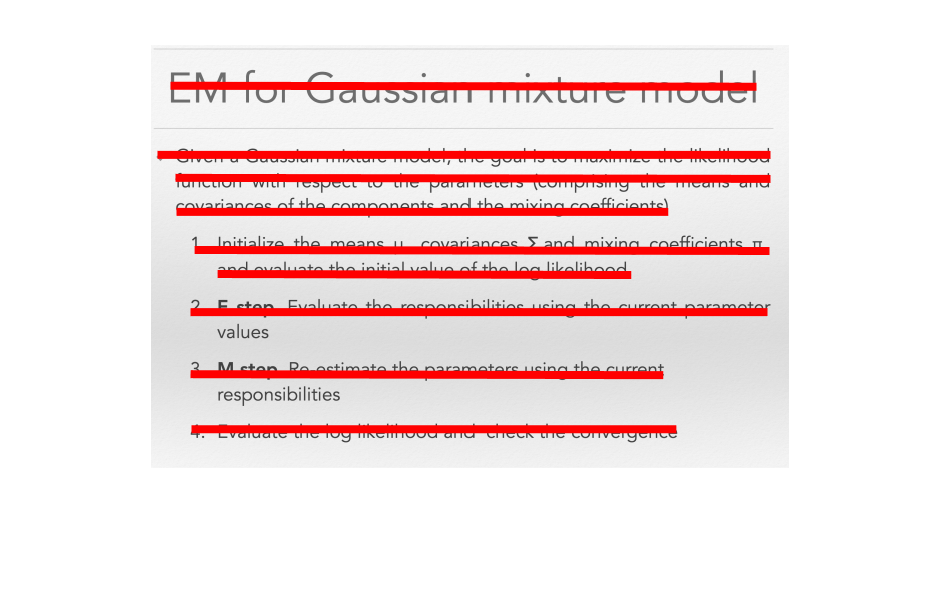

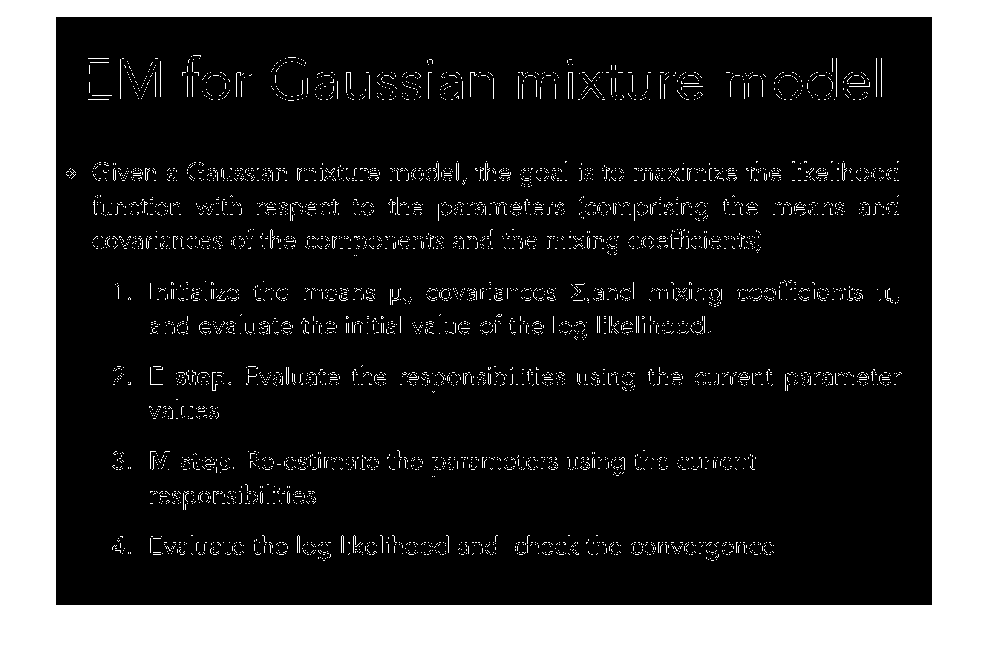

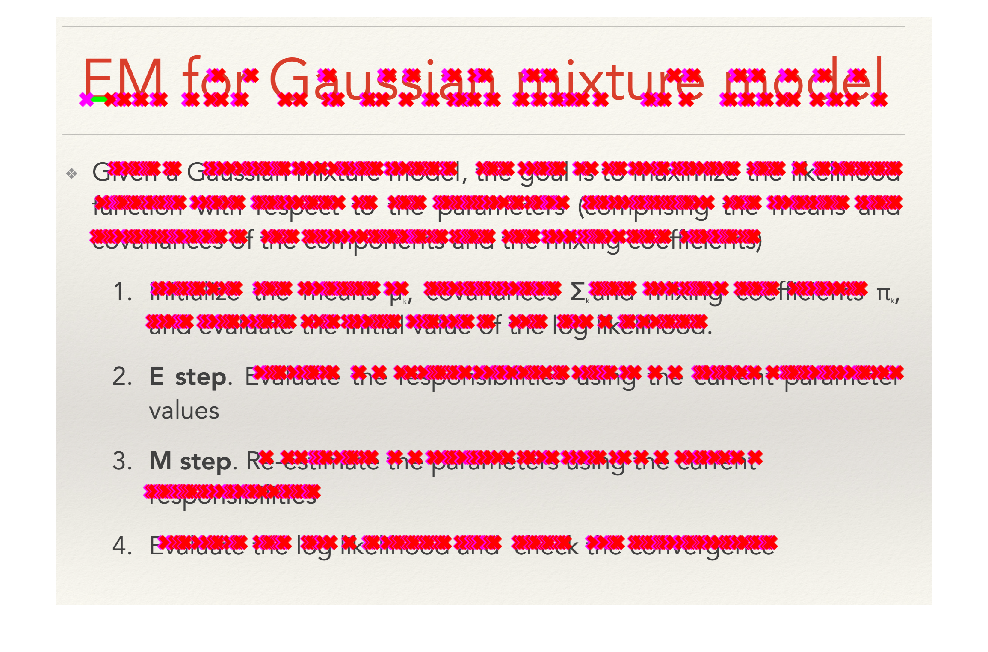

RGB = imread('gantrycrane.png');
I = im2gray(RGB);
BW = edge(I,'canny');

figure, tiledlayout(4,2)
for rho_step = [1,2]
    for theta_step = [.5,1.5]
        for threshold = [150,250]
            [H,T,R] = hough(BW,'RhoResolution',rho_step,'Theta',-90:theta_step:89);
            P  = houghpeaks(H,20,'threshold',threshold);
            lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',7);
    
            nexttile, imshow(RGB), hold on
            for k = 1:length(lines)
               xy = [lines(k).point1; lines(k).point2];
               plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
               plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','magenta');
               plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
            end
            title({['ρ=' num2str(rho_step) ' θ=' num2str(theta_step) ' threshold=' num2str(threshold)]; ...
                ['检测线条数为' num2str(length(lines))]})
        end 
   end
end

## 问题5-1

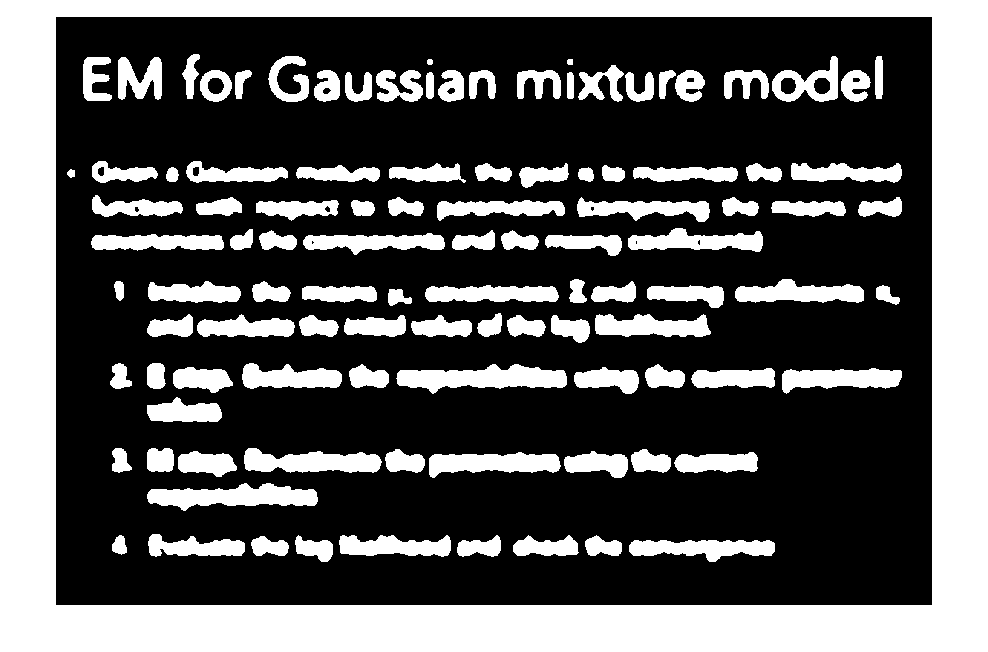

clf;
im = imread('p5-img.png');
imGray = rgb2gray(im);
imBlur = imgaussfilt(imGray,8);   
Threshold = graythresh(imBlur);
imBW = imbinarize(imBlur,Threshold);
imBW = ~imBW;
imshow(imBW)

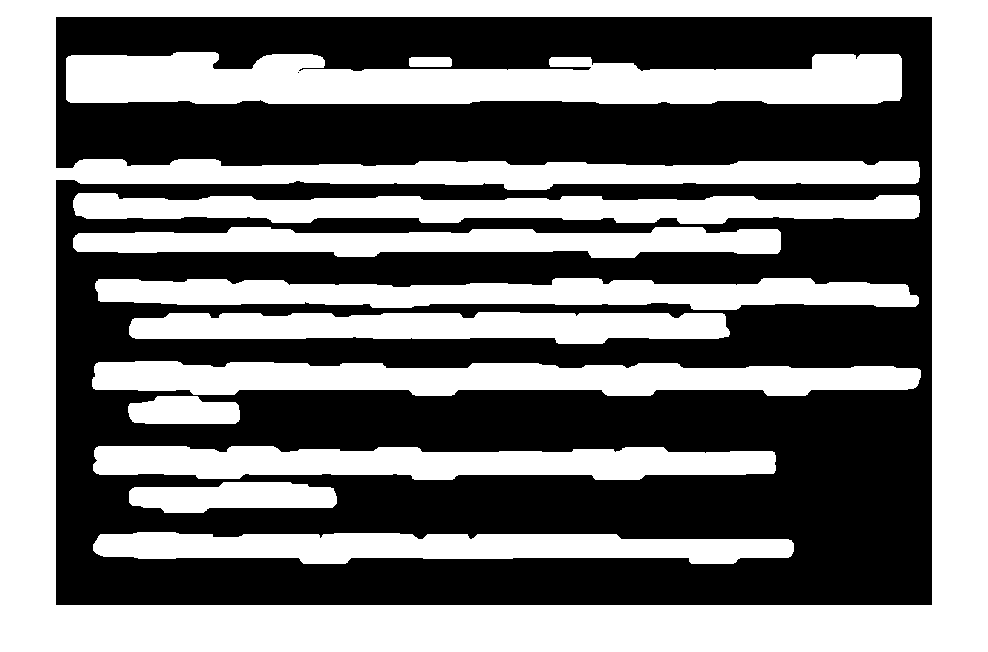


% 膨胀操作
se = strel('rectangle',[10,100]);
im_dilate = imdilate(imBW,se);
imshow(im_dilate)

% 腐蚀操作
se = strel('line',1,0);
im_erode = imerode(im_dilate,se);
imshow(im_erode)

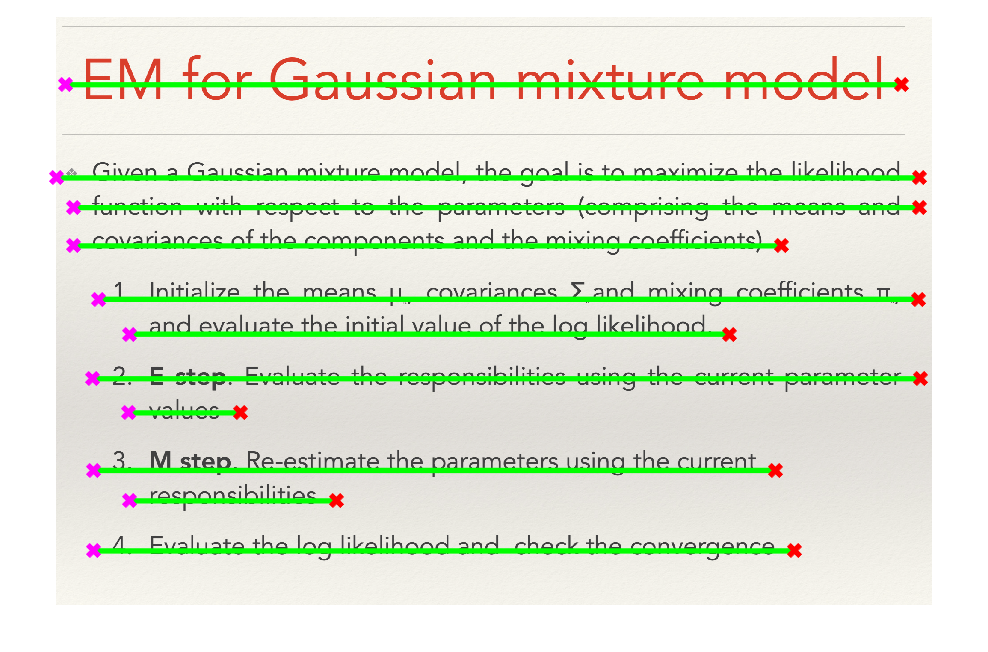


% hough变换
[H,T,R] = hough(im_erode,'RhoResolution',1,'Theta',-90);
P  = houghpeaks(H,20,'threshold',ceil(.1*max(H(:))));
lines = houghlines(im_erode,T,R,P,'FillGap',2,'MinLength',300);

% 检索合并
lines(3).point1(2) = (lines(3).point1(2)+lines(4).point1(2))/2;
lines(3).point2(2) = lines(3).point1(2);
lines(4) = [];

figure,imshow(im),hold on
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','magenta');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end
hold off

## 问题5-2

im = imread('p5-img.png');
imGray = im2gray(im);
imBlur = imgaussfilt(imGray,8);   
Threshold = graythresh(imBlur);
imBW = imbinarize(imBlur,Threshold);
imBW = ~imBW;

whiteCountPerRow = sum(imBW,2);
regions = whiteCountPerRow > 100;
startIdx = find(diff(regions)==1);
endIdx = find(diff(regions)==-1);
Ydel = (startIdx+endIdx)/2;

st = zeros(length(Ydel),1);
ed = zeros(length(Ydel),1);
for i=1:length(Ydel)
    whiteCountPerCol = sum(imBW(startIdx(i):endIdx(i),:),1);
    regions = whiteCountPerCol > 5;
    stIdx = find(diff(regions)==1);
    edIdx = find(diff(regions)==-1);
    st(i) = stIdx(1);
    ed(i) = edIdx(end);
end

imshow(im)
hold on
for i=1:length(Ydel)
    plot(st(i):ed(i),Ydel(i)*ones(size(st(i):ed(i))),'red',"LineWidth",3)
end